load coastlines;

sst1_file = "data/2022101/SNPP_VIIRS.20220411T060600.L2.SST.nc";
sst1_lat = ncread(sst1_file, "navigation_data/latitude");
sst1_lon = ncread(sst1_file, "navigation_data/longitude");
sst1 = ncread(sst1_file, "geophysical_data/sst");

%sst2_file = "data/AQUA_MODIS.20210420T182501.L2.SST.nc";
%sst2_lat = ncread(sst2_file, "navigation_data/latitude");
%sst2_lon = ncread(sst2_file, "navigation_data/longitude");
%sst2 = ncread(sst2_file, "geophysical_data/sst");

ssh_file = "data/2022101/ssh_grids_v2205_2022041112.nc";
%ncdisp(ssh_file)
ssh = ncread(ssh_file, "SLA");
ssh_lat_vec = ncread(ssh_file, "Latitude");
ssh_lon_vec = ncread(ssh_file, "Longitude");
ssh_lat = repmat(ssh_lat_vec, 1, length(ssh_lon_vec));
ssh_lon = repmat(ssh_lon_vec, 1, length(ssh_lat_vec));

%ssh_data = readmatrix("data/2023093/SSHA.10-day.20230409.bbox=60,-85,13,-23.csv");
%ssh_lat = ssh_data(:,1);
%ssh_lon = ssh_data(:,2);
%ssh = ssh_data(:,3);

chl_file = "data/2022101/VRSRCW_2022101_DAILY_SNPP_CHLORA_EC_750M.nc";
chl = ncread(chl_file, "chlor_a");
chl_lat = ncread(chl_file, "lat");
chl_lon = ncread(chl_file, "lon");

%ncdisp(ssh_file)
%ncFiles = dir(fullfile("data", '*.nc'))
%for i = 1:length(ncFiles)
%    filename = fullfile("data", ncFiles(i).name)
%    ncdisp(filename)
%end
%ncread("data/AQUA_MODIS.20210420T054001.L2.SST.nc", "geophysical_data/sst")

%sst = ncread("data/AQUA_MODIS.20210420T054001.L2.SST.nc", "geophysical_data/sst");
%sst_lat = ncread("data/AQUA_MODIS.20210420T054001.L2.SST.nc", "navigation_data/latitude");
%sst_lon = ncread("data/AQUA_MODIS.20210420T054001.L2.SST.nc", "navigation_data/longitude");

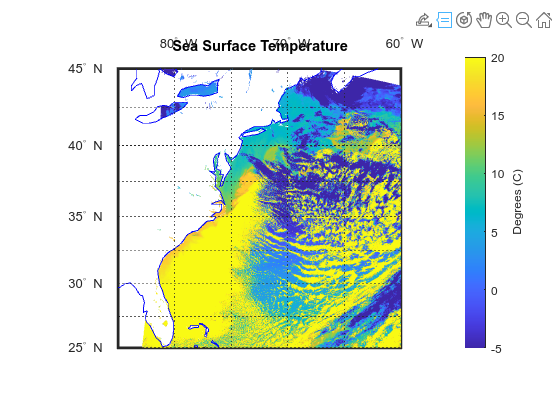

% SST
figure
%map = axesm('mercator','MapLatLimit',[35 55],'MapLonLimit',[-80,-55]);
%map = axesm('mercator','MapLatLimit',[35 60],'MapLonLimit',[-80,-45]);
map = axesm('mercator','MapLatLimit',[25 45],'MapLonLimit',[-85,-60]);
%pcolorm(sst2_lat, sst2_lon, sst2)
pcolorm(sst1_lat, sst1_lon, sst1)

%pcolorm(double(ssh_lat), double(ssh_lon), ssh)
%pcolorm(chl_lat, chl_lon, chl)
shading flat
geoshow(coastlat,coastlon);
axis off;
framem on;
gridm on;
mlabel on;
plabel on;
setm(gca,'MLineLocation',5);
setm(gca,'PlineLocation',2.5);
setm(gca,'MLabelLocation',10);
setm(gca,'PlabelLocation',5);
setm(gca,'FontSize',10);
title("Sea Surface Temperature")
c = colorbar;
clim([-5 20]);
c.Label.String = 'Degrees (C)';

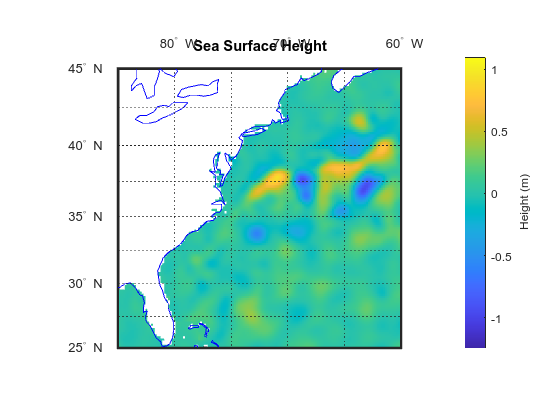

% SSH

figure
%map = axesm('mercator','MapLatLimit',[35 60],'MapLonLimit',[-80,-45]);
%map = axesm('mercator','MapLatLimit',[35 55],'MapLonLimit',[-80,-55]);
map = axesm('mercator','MapLatLimit',[25 45],'MapLonLimit',[-85,-60]);
%pcolorm(sst2_lat, sst2_lon, sst2)
%pcolorm(sst1_lat, sst1_lon, sst1)

%pcolorm(double(ssh_lat'), double(ssh_lon), ssh)
%ssh_square = reshape(ssh,63,[]);
%ssh_lat_square = reshape(ssh_lat,63,[]);
%ssh_lon_square = reshape(ssh_lon,63,[]);

pcolorm(double(ssh_lat'), double(ssh_lon), ssh);

shading flat
geoshow(coastlat,coastlon);
axis off;
framem on;
gridm on;
mlabel on;
plabel on;
setm(gca,'MLineLocation',5);
setm(gca,'PlineLocation',2.5);
setm(gca,'MLabelLocation',10);
setm(gca,'PlabelLocation',5);
setm(gca,'FontSize',10);
title("Sea Surface Height")
c = colorbar;
c.Label.String = 'Height (m)'; 

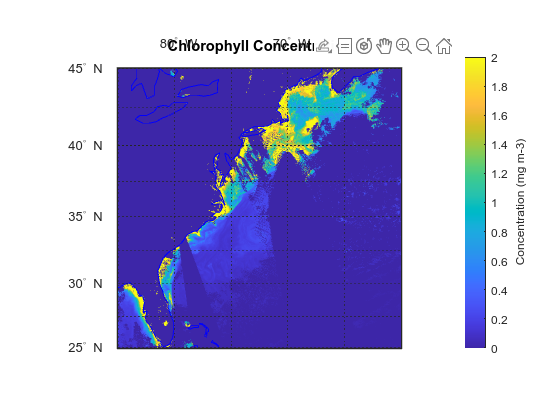

% CHL
figure
%map = axesm('mercator','MapLatLimit',[35 60],'MapLonLimit',[-80,-45]);
%map = axesm('mercator','MapLatLimit',[35 45],'MapLonLimit',[-80,-60]);
%map = axesm('mercator','MapLatLimit',[35 45],'MapLonLimit',[-80,-65]);
map = axesm('mercator','MapLatLimit',[25 45],'MapLonLimit',[-85,-60]);
%pcolorm(sst2_lat, sst2_lon, sst2)
%pcolorm(sst1_lat, sst1_lon, sst1)

%pcolorm(double(ssh_lat'), double(ssh_lon), ssh)

% Replace -999 with 0
chl(chl == -999) = 0;

% Downsample data
downsample_factor = 2;
pcolorm(chl_lat(1:downsample_factor:end,1:downsample_factor:end), ...
    chl_lon(1:downsample_factor:end,1:downsample_factor:end), ...
    chl(1:downsample_factor:end,1:downsample_factor:end))

shading flat
geoshow(coastlat,coastlon);
axis off;
framem on;
gridm on;
mlabel on;
plabel on;
setm(gca,'MLineLocation',5);
setm(gca,'PlineLocation',2.5);
setm(gca,'MLabelLocation',10);
setm(gca,'PlabelLocation',5);
setm(gca,'FontSize',10);
title("Chlorophyll Concentration")
c = colorbar;
clim([0 2]);
c.Label.String = 'Concentration (mg m-3)'; 